# Cargar información de NDVI RH26

## Declaracion de variables sobre el área de estudio

import matlab.io.hdfeos.*

close all;
disp(">>> Declarando variables...ok")

>>> Declarando variables...ok



%directorio de datos
dir_data = "D:\DATA\";
producto = 'MOD13A2';
archivo_kml = "RH26";

### Obtener la lista de archivos del producto

info_hdf = f_infohdfs2table(dir_data,producto);

>>>>> Obteniendo información de archivos sobre fechas ... 
>>>>> Analizando 1076 archivos


[num_registros_totales,~] = size(info_hdf);

#### Ventana para el mapa region hidrografica rio panuco


% % %Ventana para el mapa region hidrografica rio panuco
lon_mapa = [-101.6 -97.40];
lat_mapa = [ 18.7  24.3];

% lon_mapa = [-102 -97];
% lat_mapa = [ 18  25];
[coord_1k_v6_inicio,coord_1k_v6_tam,coord_1k_v7_inicio,coord_1k_v7_tam,ndvi_tam]...
    = f_get_coordinates(dir_data,"RH26",info_hdf,31);

>>>>> Obteniendo la zona de estudio
>>>>> Analizando 2 archivos
umbral LON:15376
umbral LAT:18476
A LON:7688


## Obtener latitud y longitud

if (num_registros_totales > 0)
    % Obtener matrices de latitud y longitud
    [lat,lon,ndvi] = f_get_latlon(info_hdf,coord_1k_v6_inicio,coord_1k_v6_tam,coord_1k_v7_inicio,coord_1k_v7_tam);
end

>>>>> Obteniendo latitud y longitud


## Crear el área de estudio

% crear matriz de 0 y 1 que delimitan el área de estudio
ae = exist("study_area_"+archivo_kml+"_"+producto,"var");
if ae == 0  %% no existe
    ae = exist("study_area_"+archivo_kml+"_"+producto+".mat","file");
    if ae == 2
        disp(">>> Cargando área de estudio");
        load ("study_area_"+archivo_kml+"_"+producto);
    else
        study_area = f_create_study_area(dir_data+'KML\'+archivo_kml+'.kml',lat,lon);
        save ("study_area_"+archivo_kml+"_"+producto+".mat",'study_area');
    end
else
    if( numel(study_area) ~= ( ndvi_tam(1)*ndvi_tam(2)) )
        disp("La variable area_estudio sera sustituida");
        study_area = f_create_study_area(dir_data+'KML\'+archivo_kml+'.kml',lat,lon);
        save ("study_area_"+archivo_kml+"_"+producto+".mat","study_area_"+archivo_kml+"_"+producto);
    else
        disp(">>> Área de estudio existente");
    end
end

Creando área de estudio!!!


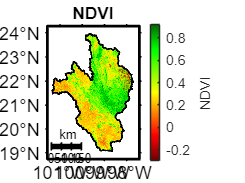


ndvi = double(ndvi) .* 0.0001;
ndvi(study_area==false)=nan;
figure;
f_draw_map(lon_mapa,lat_mapa,lon,lat,ndvi,"NDVI",[],"NDVI","NDVI");
f_draw_kml(dir_data,archivo_kml,1,'k');

disp("a");

a


## Leer los arreglos de datos

% Realizar la consulta de los datos que se requieren
tmp = find(  info_hdf.anio == 2023 );
info_consulta = info_hdf(tmp,:);

[num_registros,~] = size(info_consulta);

% arreglo 3d de ndvi por día
arr_ndvi = zeros( ndvi_tam(1),ndvi_tam(2) ,num_registros);
% arreglo 3d para la calidad del pixel
arr_ndvi_qa = zeros( ndvi_tam(1),ndvi_tam(2) ,num_registros);
arr_ndvi_nan = zeros( ndvi_tam(1),ndvi_tam(2) ,num_registros);

% arreglo 3d de ndvi por día con filtro Saviztky
arr_ndvi_sgf = zeros( ndvi_tam(1),ndvi_tam(2) ,num_registros);
% arreglo 3d de ndvi por día con filtro Lanczos
arr_ndvi_lf = zeros( ndvi_tam(1),ndvi_tam(2) ,num_registros);

#### Leer los datos

bp=waitbar(0,'Obteniendo información de archivos MODIS'); 
for i=1:num_registros
    [ndvi,~,~,disponibilidad] = f_get_ndvi(info_consulta(i,:),coord_1k_v6_inicio,coord_1k_v6_tam,coord_1k_v7_inicio,coord_1k_v7_tam);

    % recortar el area de estudio
    %ndvi(study_area==false)=NaN;
    %disponibilidad(study_area==false)=NaN;

    %almacenar en el arreglo en 3d
    arr_ndvi(:,:,i) = ndvi;
    arr_ndvi_qa(:,:,i) = disponibilidad;
 
    arr_ndvi_lf(:,:,i) = ndvi;
    arr_ndvi_sgf(:,:,i) = ndvi;

    %barra de progreso
    waitbar(i/num_registros,bp,sprintf('Obteniendo información de archivos MODIS (%3.0f%%) ',(i/num_registros*100)));
end
close(bp); 


#### Mostrar el promedio de NDVI

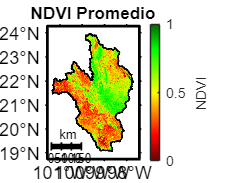

ndvi_prom = m_mean_3dpp(arr_ndvi);
ndvi_prom(study_area==false)=nan;

f_draw_map(lon_mapa,lat_mapa,lon,lat,ndvi_prom,"NDVI Promedio",[0 1],"NDVI","NDVI");
f_draw_kml(dir_data,archivo_kml,1,'k');

## Filtrar con Lanczos y Savitzky-Golay 

%Mejores parametros para el filtro Lanczos
dT = 23;
cf= 1/46;

% Mejores parametros para Savitzky-Golay
order = 3;
framelen = 7;

bp=waitbar(0,'Generando series de tiempo con filtros'); 
for i=1:ndvi_tam(1)
     for j=1:ndvi_tam(2)
         if study_area(i,j) == true

             S  = reshape( arr_ndvi(i,j,:),[],1);
             SNan =  reshape( arr_ndvi_nan(i,j,:),[],1);

             arr_ndvi_nan(i,j,:) = f_rm_pixel_baja_calidad(arr_ndvi(i,j,:),arr_ndvi_qa(i,j,:));

             [arr_ndvi_nan(i,j,:),~] = f_fillmissing_linear(arr_ndvi_nan(i,j,:),2);

             [xs,~,~,~,~] = lanczosfilter(S,dT,cf,[],'low');  
             arr_ndvi_lf(i,j,:) = xs;

             arr_ndvi_sgf(i,j,:) = sgolayfilt(S,order,framelen);

         end

     end
     waitbar(i/ndvi_tam(1),bp,sprintf('Generando series de tiempo con filtros (%3.0f%%) ',(i/ndvi_tam(1)*100)));
end
close (bp);

#### Mostrar el promedio de NDVI FILTRO LANCZOS de toda la serie

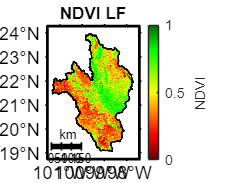

ndvi_prom = m_mean_3dpp(arr_ndvi_lf);
ndvi_prom(study_area==false)=nan;

f_draw_map(lon_mapa,lat_mapa,lon,lat,ndvi_prom,"NDVI LF",[0 1],"NDVI","NDVI");
f_draw_kml(dir_data,archivo_kml,1,'k');


% exportgraphics(gca,"img/promedio_ndvi_lf.png",'Resolution',300) 



#### Mostrar el promedio de NDVI FILTRO SAVITZKY de toda la serie

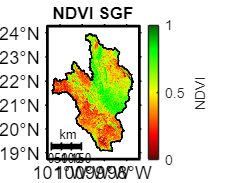

ndvi_prom = m_mean_3dpp(arr_ndvi_sgf);
ndvi_prom(study_area==false)=nan;

f_draw_map(lon_mapa,lat_mapa,lon,lat,ndvi_prom,"NDVI SGF",[0 1],"NDVI","NDVI");
f_draw_kml(dir_data,archivo_kml,1,'k');


% exportgraphics(gca,"img/promedio_ndvi_sgf.png",'Resolution',300) 

